# Slope Variation Simulation - Realistic RevA

## [1] Simulator Initialization

Initialize the simulator by setting default parameters for the attacker and defender

simulator = Simulator();
%setup the defender's chirp parameters

simulator.load_realistic_defender_params;
simulator.load_realisitc_attacker_params;

%print out key parameters
simulator.Defender.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.00 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 43.00 us
	 Chirp Tx Bandwidth: 		 462.68 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 0.00 nm


simulator.Defender.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.60 ms


simulator.Defender.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Attacker.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.00 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 43.00 us
	 Chirp Tx Bandwidth: 		 462.68 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 0.00 nm


simulator.Attacker.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.50 ms
	 Active Frame Time 		 1.60 ms


simulator.Attacker.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


%apply timing offsets as desired
simulator.Defender.timing_offset_us = 0;
simulator.Attacker.timing_offset_us = (range2time(75,physconst('LightSpeed')))* 1e6/2; %propogating 1 way, distance defaults to 7m 

%configure the FMCW parameters
simulator.configure_FMCW_parameters();

%load default target, attacker, and defender positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_defender_position_and_velocity();

%disable the target for this simulation
simulator.SimulatedTarget.enabled = false;

## [2] Plot the Victim Chirp

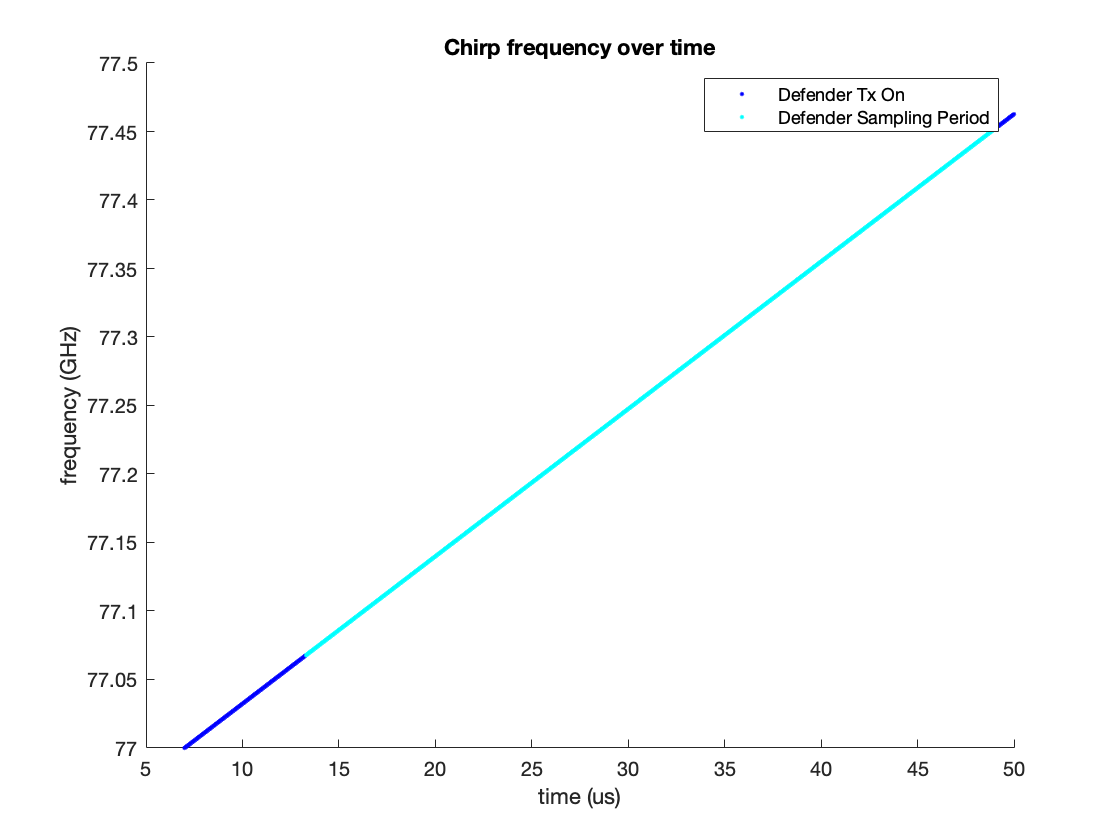

figure;
ax = axes;
defender_chirp = 1;
defender_frame = 1;
simulator.plot_specified_radar_chirp(ax,simulator.Defender,defender_chirp, defender_frame);

## [3] Overlay Attacker Interference (if any)

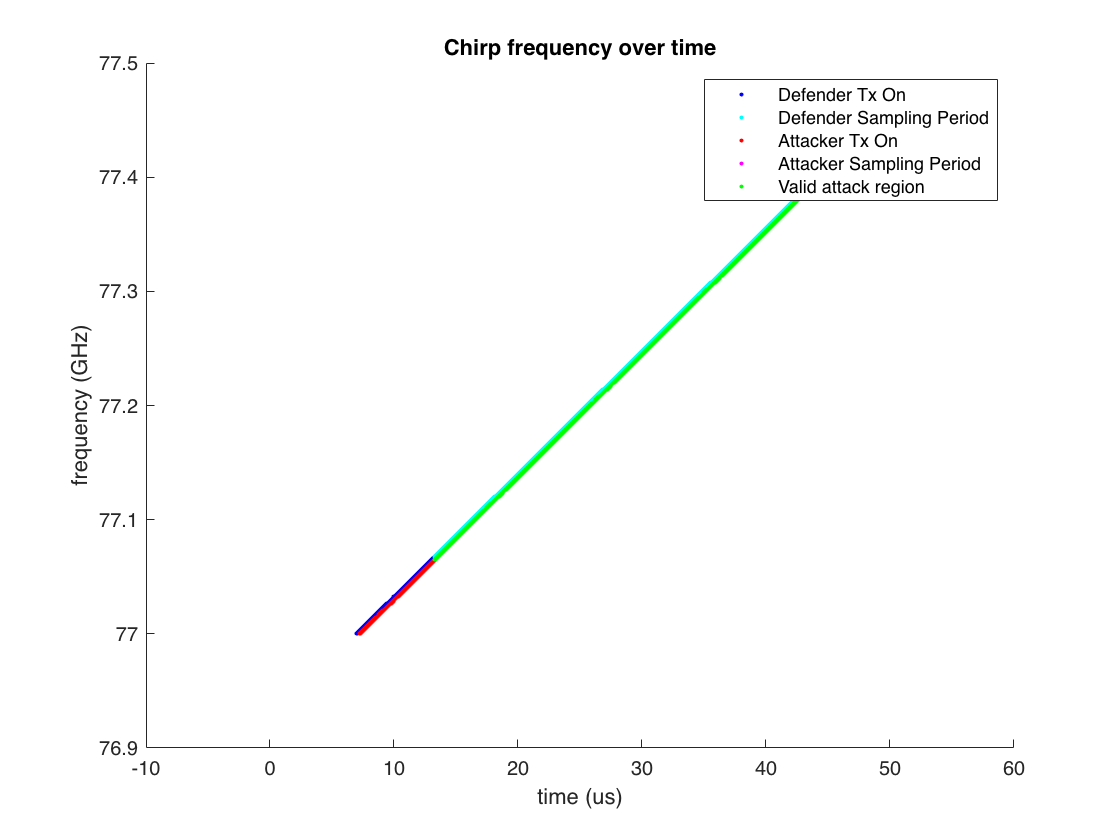

clf;
ax = axes;
simulator.plot_attacker_and_defender_chirps(ax,defender_frame,defender_chirp);

## [4] Plot Victim Frame

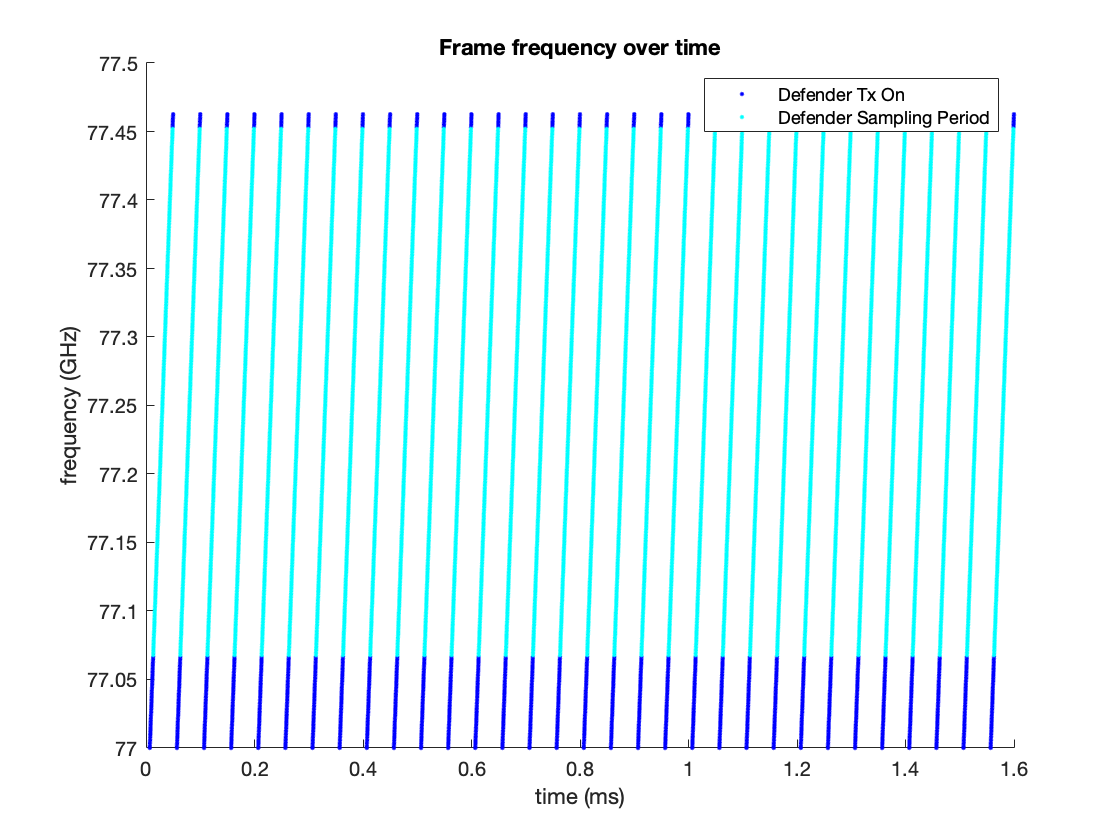

clf;
ax = axes;
simulator.plot_specified_radar_frame(ax,simulator.Defender,defender_frame);

## [5] Overlay Attacker Interference

Here, the green regions identify that the attacker is successfully interfering with the defender

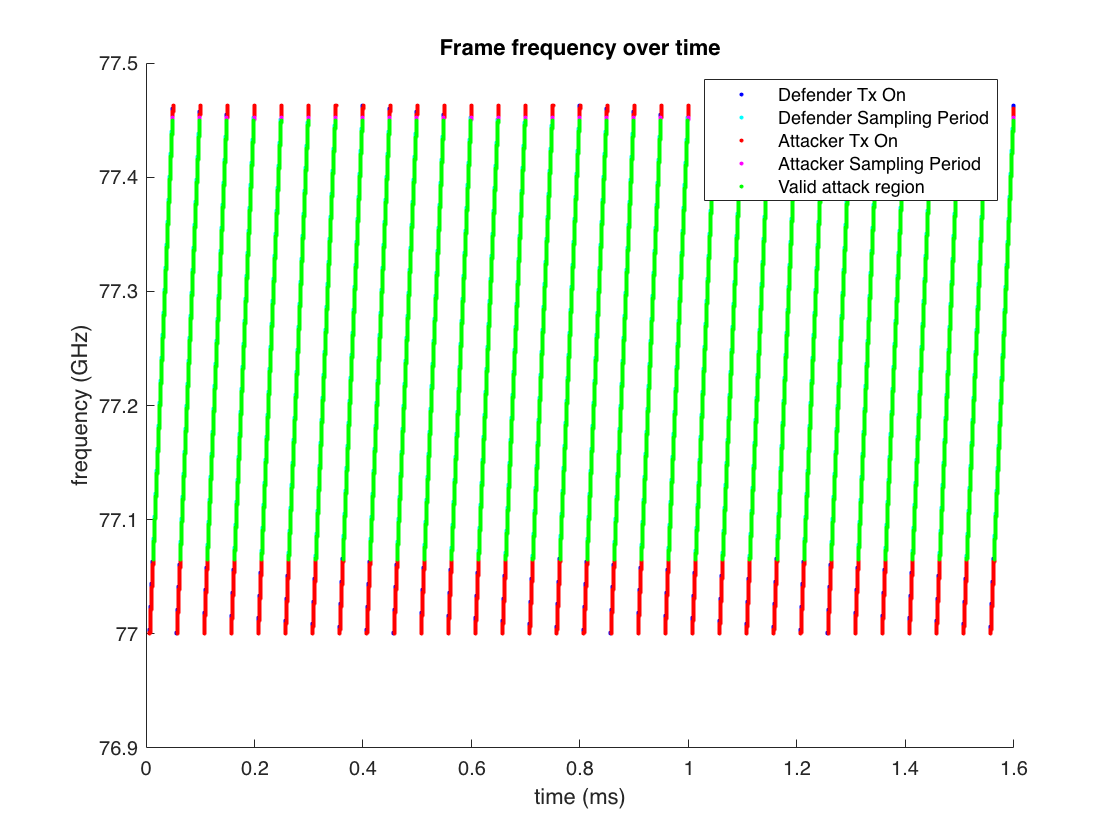

clf;
ax = axes;
simulator.plot_attacker_and_defender_frames(ax,defender_frame)

## [6] Generate the FMCW Waveform for a victim chirp and plot its spectogram

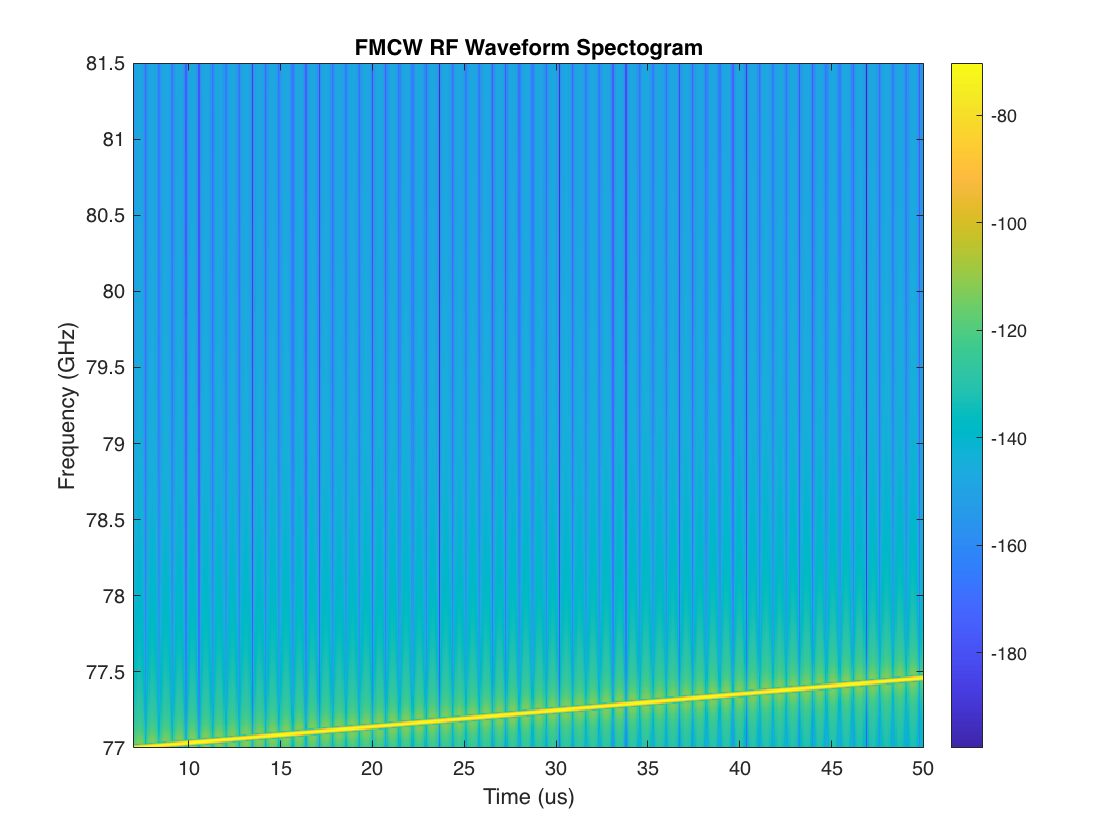

clf;
ax = axes;
simulator.FMCW_plot_radar_chirp_spectogram(ax,simulator.Defender,defender_frame,defender_chirp);

## [7] Plot the resulting FFT when the slope is ideal

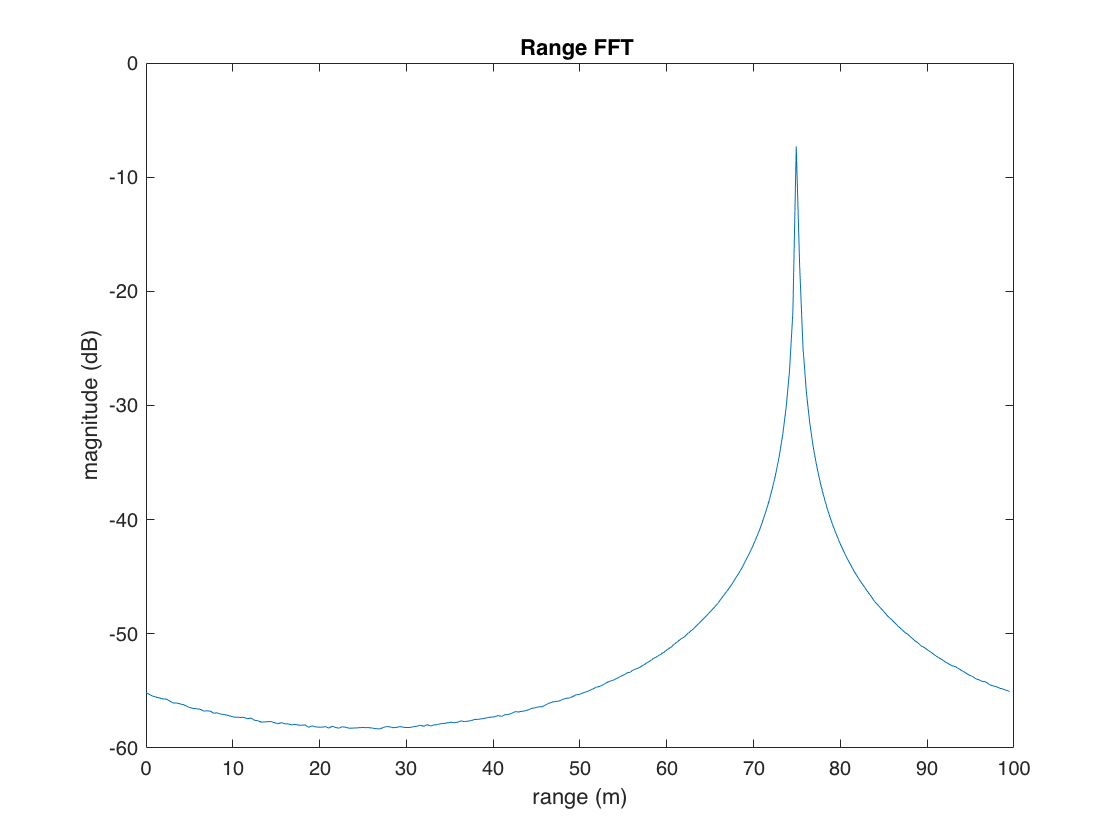

clf;
ax = axes;
[sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
simulator.FMCW_plot_range_fft(ax,simulator.Defender,sampled_IF_sig);

## [8] Run Sweep of Different Slopes

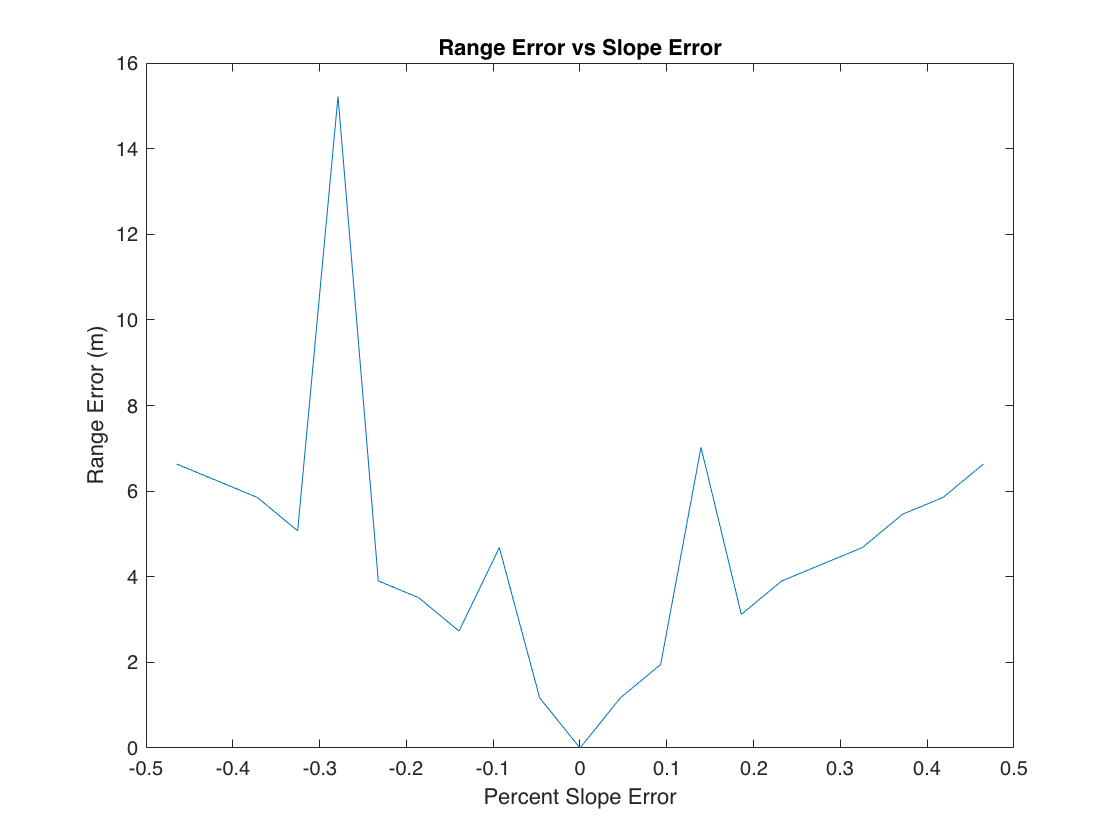

clf;
ax = axes;

center_frequency = simulator.Attacker.FrequencySlope_MHz_us;
increment = 0.005;                                               %step size in MHz/us
sweep_width_MHz_us = 0.05;                                       %sweep width in MHz/us

slope_errors = -sweep_width_MHz_us: increment : sweep_width_MHz_us;
range_errors = zeros(1,size(slope_errors,2));

%compute the range when slope error is zero
[sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
[fft_out,ranges] = simulator.FMCW_compute_range_fft(simulator.Defender,sampled_IF_sig);
[peaks,locations] = findpeaks(fft_out,'MinPeakHeight',-10,SortStr='descend');

ideal_range = ranges(locations(1));

for i = 1:size(slope_errors,2)
%     clc;
%     fprintf('processing slope %d of %d\n',i,size(slope_errors,2));
    slope_error = slope_errors(i);
    simulator.Attacker.FrequencySlope_MHz_us = center_frequency + slope_error;

    %recompute attacker calculated values
    simulator.Attacker.compute_calculated_vals();

    %reconfigure the FMCW parameters
    simulator.configure_FMCW_parameters();

    [sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
    [fft_out,ranges] = simulator.FMCW_compute_range_fft(simulator.Defender,sampled_IF_sig);
    [peaks,locations] = findpeaks(fft_out,'MinPeakHeight',-24,'SortStr','descend');
    range_errors(i) = abs(ideal_range - ranges(locations(1)));
end
% plot(ax,slope_errors,range_errors);
% title('Range Error vs Slope Error');
% xlabel('Slope Error (MHz/us)');
% ylabel('Range Error (m)');

%for plotting percent error in slope error
slope_errors_percentage = (slope_errors)/center_frequency * 100;
plot(ax,slope_errors_percentage,range_errors);
title('Range Error vs Slope Error');
xlabel('Percent Slope Error');
ylabel('Range Error (m)');

## [9] Plot spectogram of received signal with worst slope error

Notice that there is no perceived difference in the slope

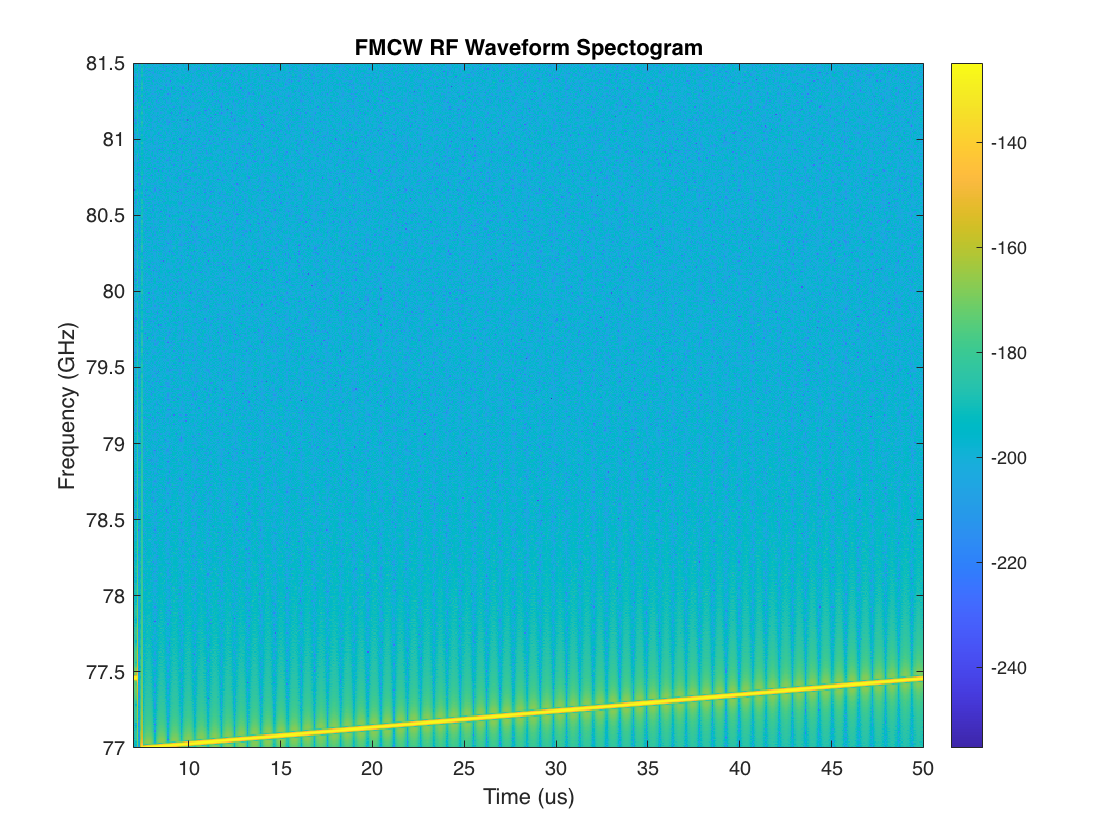

clf;
ax = axes;
[sampled_IF_sig,combined_received_sigs, defender_waveform_sig, defender_waveform_t] = simulator.FMCW_simulate_scenario_chirp(defender_chirp,defender_frame);
simulator.plot_RF_spectogram(ax,combined_received_sigs,simulator.Defender.FMCW_sampling_rate_Hz,defender_waveform_t);

## [10] Plot the received IF signal with the worst slope error

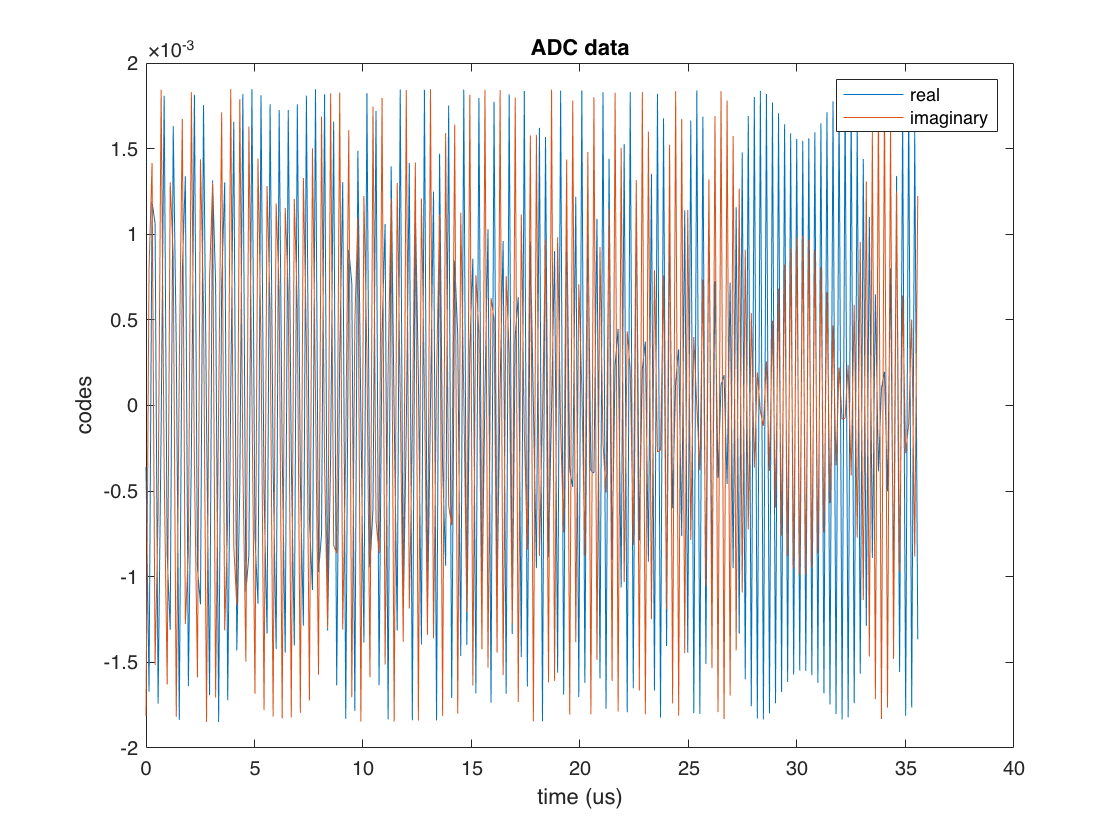

clf;
ax = axes;
simulator.FMCW_plot_sampled_IF_data(ax, simulator.Defender, sampled_IF_sig);

## [10] Compute FFT of the IF signal with the worst slope error

Notice how the range FFT has now shifted and spread out as the slope error increased

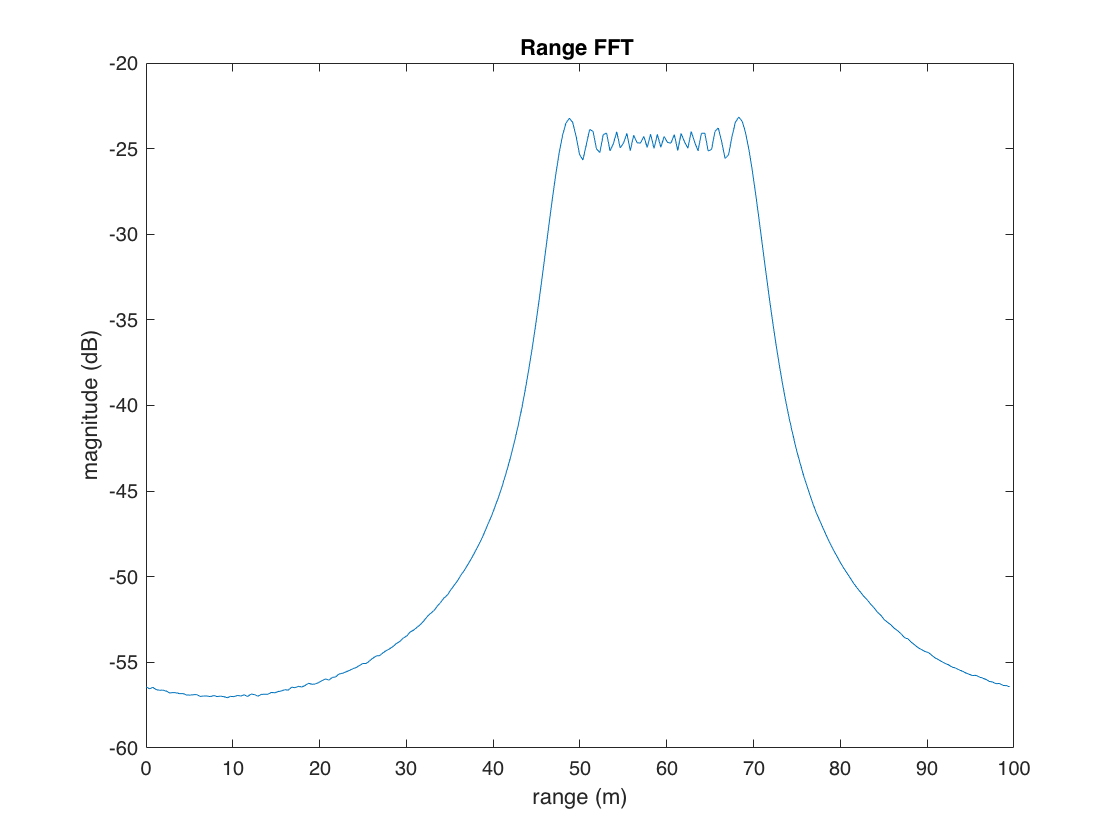

clf;
ax = axes;
simulator.FMCW_plot_range_fft(ax,simulator.Defender,sampled_IF_sig);